clc
clear all
format long

% Program Start
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## 1. Read input files

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Load the stock weekly prices and factors weekly returns
adjClose = readtable('Project1_Data_adjClose.csv');
adjClose.Properties.RowNames = cellstr(datetime(adjClose.Date));
dates = datetime(adjClose.Date);
size_adjClose = size(adjClose);
adjClose = adjClose(:,2:size_adjClose(2));

factorRet = readtable('Project1_Data_FF_factors.csv'); %, 'ReadRowNames', true);

factorRet.Properties.RowNames = cellstr(datetime(factorRet.Date));

yearlyReturn = readtable('yearly_ret.xlsx'); %xlsread('Project1_Data_adjClose_yearly_ret','Project1_Data_adjClose_yearly_r');
yearlyReturn = yearlyReturn(:,2:end);
yearlyReturn.Properties.RowNames = cellstr(dates((size(dates,1)-size(yearlyReturn,1)+1):end, :));

monthlyReturn = readtable('monthly_ret.xlsx'); %xlsread('Project1_Data_adjClose_yearly_ret','Project1_Data_adjClose_yearly_r');
%monthlyReturn = monthlyReturn(:,2:end);
% monthlyReturn.Properties.RowNames = cellstr(dates(1:size(monthlyReturn,1), :));
avgMonthlyReturn = table2array(readtable('averaged_monthly_ret.xlsx'));

% Identify the tickers and the dates 
tickers = yearlyReturn.Properties.VariableNames';

% Calculate the stocks' weekly EXCESS returns
prices  = table2array(adjClose);
returns = ( prices(2:end,:) - prices(1:end-1,:) ) ./ prices(1:end-1,:);
returns = array2table(returns);
returns.Properties.VariableNames = tickers;
returns.Properties.RowNames = cellstr(datetime(factorRet.Properties.RowNames));

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## 2. Define your initial parameters

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Start of in-sample calibration period 
calStart = datetime('2013-01-01');
calEnd   = calStart + calmonths(12*2) - days(1);

% Start of out-of-sample test period 
testStart = datetime('2015-01-01');
testEnd   = testStart + calmonths(12) - days(8);

% Number of investment periods (each investment period is 6 months long)
NoPeriods = 6;

% Determine hyperparameters based on adjClose and monthlyReturn
[NoTotalDates, NoAssets] = size(adjClose);
[NoTotalMonths, NoAssets] = size(monthlyReturn);

% yearly training returns and prices from 2012 Jan to 2014 Dec
trainingReturns_yr = table2array( yearlyReturn( calStart <= dates & dates <= calEnd, :) );
lastYearTrainingReturns_yr = table2array( yearlyReturn( calEnd-calmonths(12)+days(1) <= dates & dates <= calEnd, :) );

% yearly testing returns from 2015 Jan to 2015 Dec
%testingReturns = table2array( yearlyReturn( testStart <= dates & dates <= testEnd, :) );

% weekly testing returns from 2015 Jan to 2015 Dec
testingReturns_weekly = table2array( returns( testStart <= dates & dates <= testEnd, :) );

% monthly training returns and prices from 2012 Jan to 2014 Dec
trainingReturns_mth = table2array( monthlyReturn( calStart <= dates & dates <= calEnd, :) );
lastYearTrainingReturns_mth = table2array( monthlyReturn( calEnd-calmonths(12)+days(1) <= dates & dates <= calEnd, :) );

% monthly testing returns from 2015 Jan to 2015 Dec
testingReturns = table2array( monthlyReturn( calStart <= dates & dates <= calEnd, :) );

% Data Mean Year
mu_entire_training_yr = geomean(trainingReturns_yr, 1) - 1;

mu_last_year_yr = geomean(lastYearTrainingReturns_yr, 1) - 1;


% Data Mean Month
mu_entire_training_mth = geomean(1+trainingReturns_mth, 1) - 1;

mu_last_year_mth = geomean(1+lastYearTrainingReturns_mth, 1) - 1;


% Data Variance Year
cov_entire_training_yr = cov(trainingReturns_yr-1);
cov_last_Year_yr = cov(lastYearTrainingReturns_yr-1);

% Data Variance Month
cov_entire_training_mth = cov(trainingReturns_mth);
cov_last_Year_mth = cov(lastYearTrainingReturns_mth);

no_splits = 100;
generated_ret = mvnrnd(mu_entire_training_mth, cov_entire_training_mth, no_splits); % 20 assets = 20 rows; scenarios in columns
exp_generated_ret = geomean(1+generated_ret,1)-1; % for VSS first term


b = 1000

b =         1000


G = [500, 900, 1000, 1100, 1200, 1500, 2000, 10000]

G =          500         900        1000        1100        1200        1500        2000       10000


## CALL FUNCTION for Weights

for i = 1:size(G, 2)
    [x,fval] = Solver_mat(1+generated_ret, b, G(1,i));
    fval = -1*fval;
    [x_expected_scenarios, fval_expected_scenarios] = Solver_mat(exp_generated_ret, b, G(1,i)); %VSS first term

    for j = 1:no_splits
        weights{i,j} = [x((1:NoAssets), 1) x((NoAssets*j+1):(NoAssets*(j+1)), 1)];
    end
    weights_exp_scenarios{i} = [x_expected_scenarios((1:NoAssets), 1) x_expected_scenarios(((NoAssets+1):NoAssets*2), 1)];
    weights_mat = cat(3, weights{i,:});
    weights_mean{i} = mean(weights_mat, 3);
    
end

b =         1000



Optimal solution found.



b =         1000



Optimal solution found.



b =         1000



Optimal solution found.



b =         1000



Optimal solution found.



b =         1000



Optimal solution found.



b =         1000



Optimal solution found.



b =         1000



Optimal solution found.



b =         1000



Optimal solution found.



b =         1000



Optimal solution found.



b =         1000



Optimal solution found.



b =         1000



Optimal solution found.



b =         1000



Optimal solution found.



b =         1000



Optimal solution found.



b =         1000



Optimal solution found.



b =         1000



Optimal solution found.



b =         1000



Optimal solution found.



fig1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.940000000000000 0.940000000000000 0.940000000000000]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


fig1 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.940000000000000 0.940000000000000 0.940000000000000]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


fig1 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.940000000000000 0.940000000000000 0.940000000000000]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


fig1 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.940000000000000 0.940000000000000 0.940000000000000]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


fig1 =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.940000000000000 0.940000000000000 0.940000000000000]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


fig1 =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.940000000000000 0.940000000000000 0.940000000000000]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


fig1 =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.940000000000000 0.940000000000000 0.940000000000000]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


fig1 =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.940000000000000 0.940000000000000 0.940000000000000]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


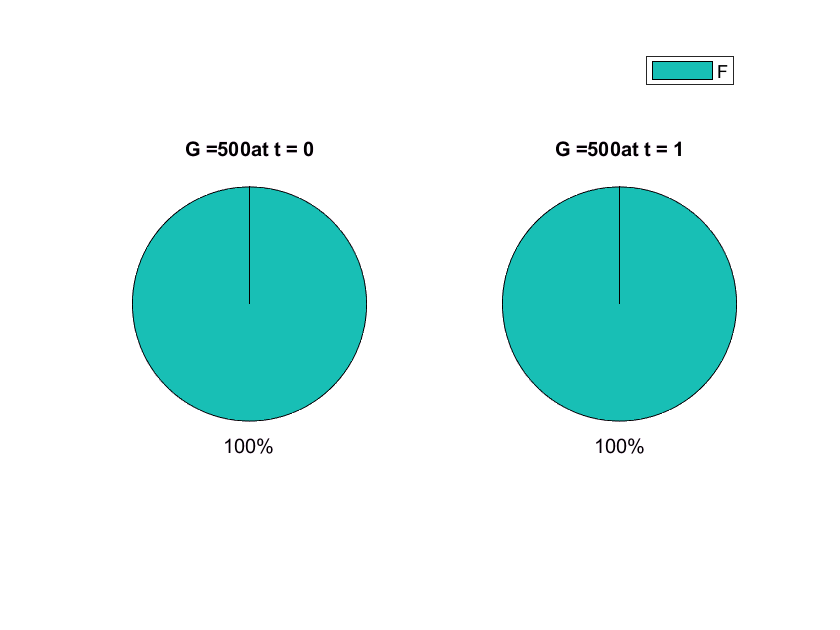

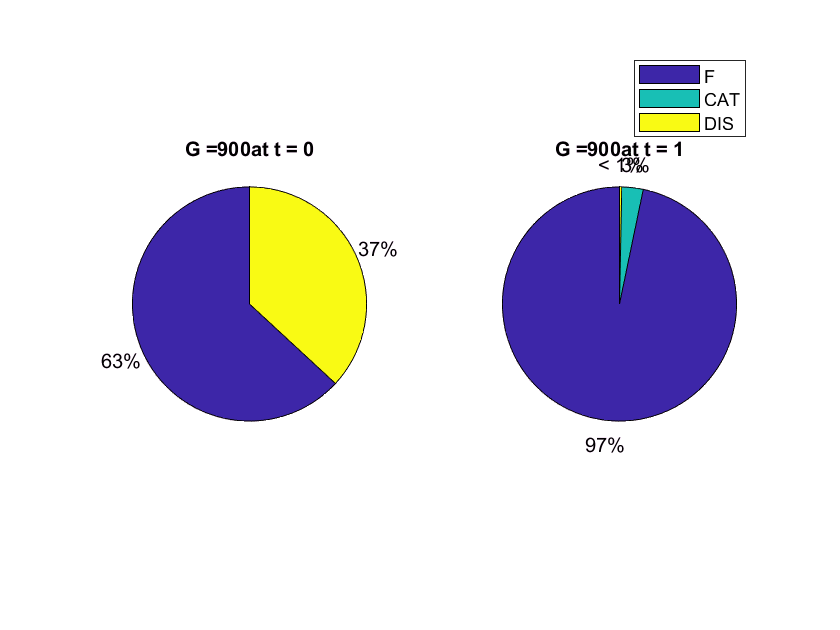

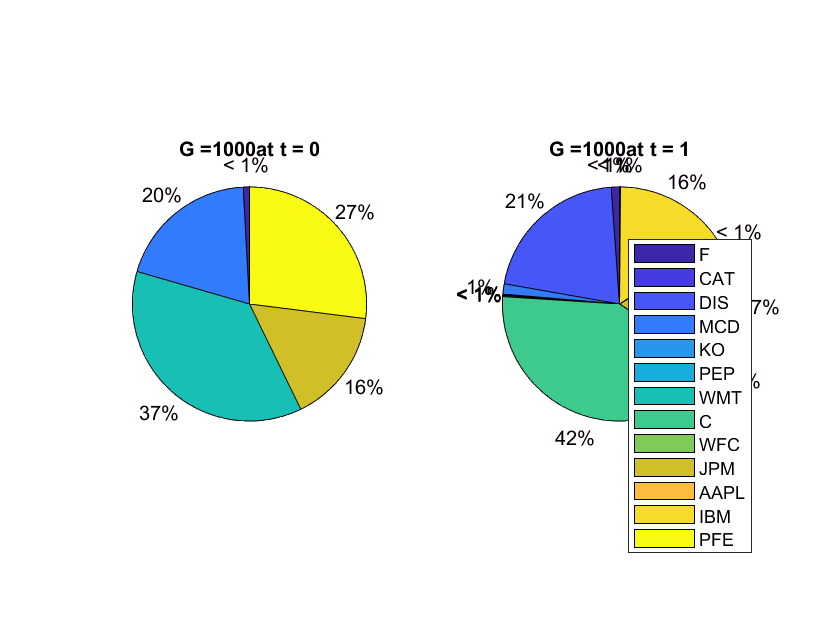

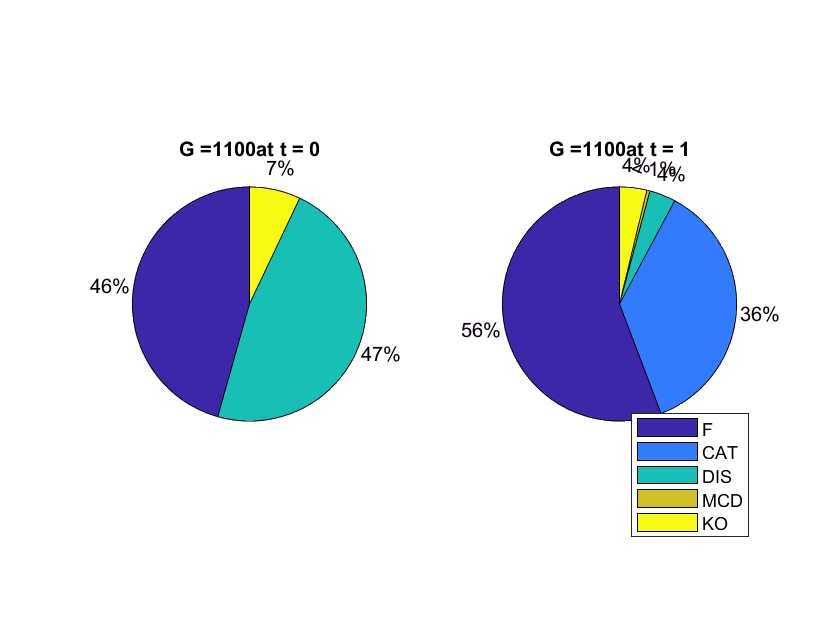

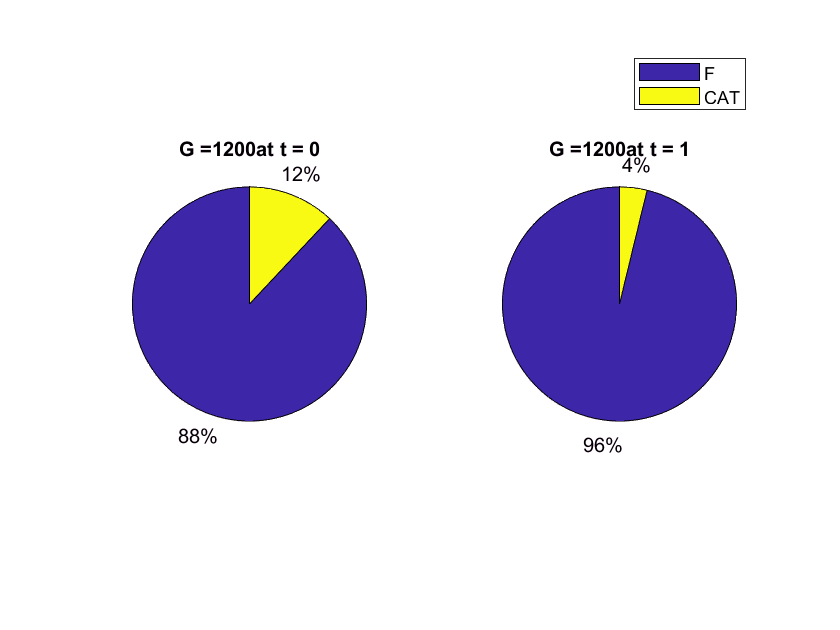

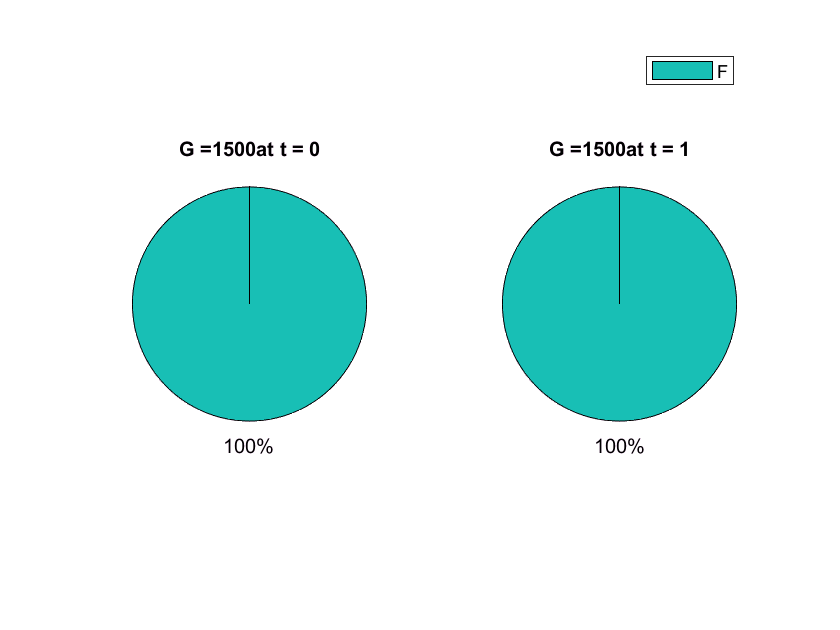

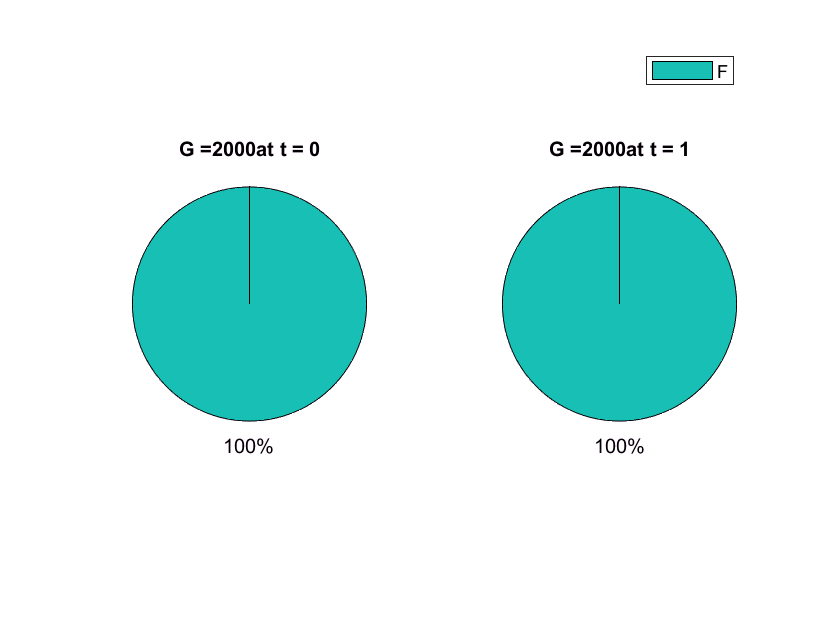

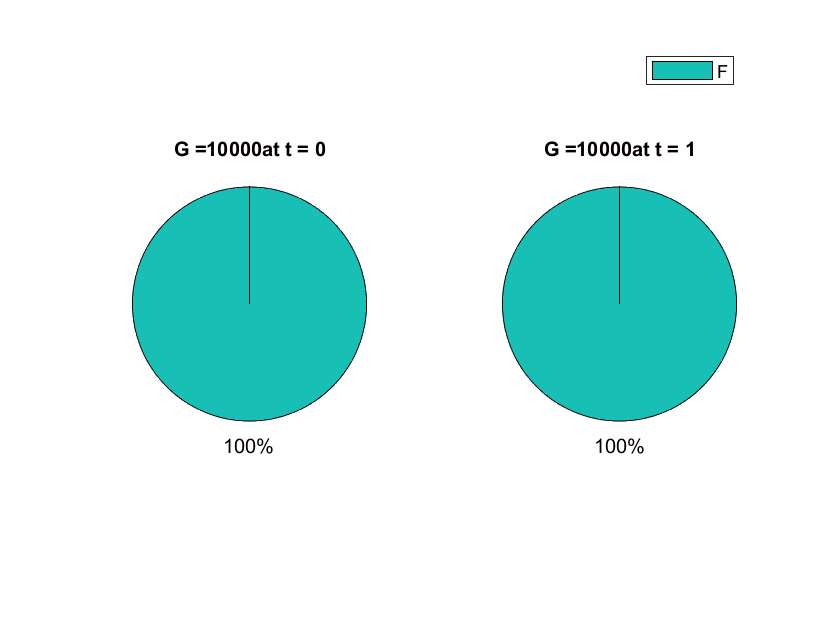

for i = 1:size(G,2)
    for s = 1:size(no_splits)
        portfRet{i,s} = diag((1+avgMonthlyReturn(1:2, :))*weights{i,s});
        
    end
%     figures{i} = figure(i)
    fig1 = figure(i)

    X = weights_mean{i}(:,1)';
    labels = tickers;
    ax1 = subplot(1,2,1);
    p{(i-1)*2+1} = pie(ax1,X);
%     p{(i-1)*2+1}.FontSize = 5;
    title(ax1,strcat('G = ', num2str(G(1,i)),'at t = 0'),  'FontSize', 10);
%     ax1.FontSize = 5;
    
    Y = weights_mean{i}(:,2)';
    ax2 = subplot(1,2,2);
    p{(i-1)*2+2} = pie(ax2,Y);
%     p{(i-1)*2+2}.FontSize = 5;
    title(ax2,strcat('G = ', num2str(G(1,i)),'at t = 1'), 'FontSize', 10);
%     ax2.FontSize = 5;
    legend(labels, 'Location', 'best', 'Orientation', 'vertical');
    
    print(fig1,strcat('portfolio_distribution_', num2str(i)),'-dpng','-r0');
    

%     saveas(figure(1),[pwd '/subFolderName/myFig.fig']);
    
end




portfRet_mat = cat(3, portfRet{:});
expected_portfRet_across_scenarios = mean(portfRet_mat, 3);
weights_mean_mat = cat(3, weights_mean{:});
for i =1:size(G,2)
    portfRet_testing(i,:) = diag((1+avgMonthlyReturn(1:2,:))*normc(weights_mean{i}))';
end
portfValue = weights*testingReturns_weekly';

Undefined function 'mtimes' for input arguments of type 'cell'.


plot(portfValue);

% y1[2]- y2[2]- y3[2]- y1[2]+ y2[2]+ y3[2]+ y1[3]- y2[3]- y3[3]- y1[3]+ y2[3]+ y3[3]+ 
% Aeq = [eye(3) eye(3) -1*eye(3) eye(3) zeros(3, no_var-12); % s = 1 and j = 1 2 3
%     eye(3) eye(3) zeros(3,6) -1*eye(3) eye(3) zeros(3, no_var-18); % s = 2 and j = 1 2 3
%     eye(3) eye(3) zeros(3,12) -1*eye(3) eye(3)] % s = 3 and j = 1 2 3